# Estimating uncertainty for your Mono Lake model using Monte Carlo methods

We can make predictions of future lake levels using average parameter values, but this approach doesn't easily allow us to estimate the uncertainty of the results. In this activity we will use Monte Carlo methods to add a stochastic element to our model.

## Learning Goals

At the end of this activity you will be able to :

- Estimate model uncertainty using Monte Carlo methods in MATLAB

- Use a probabilistic model to evaluate the efficacy of water diversion policies

- Present model results and recommendations in concise oral presentations and written reports

New MATLAB functions and concepts:

- if, elesif, else

- LineWidth

- saveas

## Creating our model script

## 1.  Header

Start by writing some general header comments describing the purpose of your script (you can edit these later).

% Mono Lake model including Monte Carlo uncertainty

## 2.  Adding Data

Copy over lines from your initial Mono Lake script that read in the relevant model paramater and comparison data (pt. 3, except initial value part).

% Read in Vorster measured data using xlsread
    % All data are in cells B2:B48, The individal sheets contain the following data:
    % 1. Elevation [feet above msl], 2. Volume [Acre-Feet], 3. Area [Acres],
    % 4. Gauged stream [flow, Acre-Feet per Year], 5. Diversion [flow, Acre-Feet per Year]
    % 6. Ungauged [flow, Acre-Feet per Year], 7. Precipitation [rate, Feet per Year],
    % 8. Evaporation [rate, Feet per Year].

% read in data sets that we will use in the model.
    % The MATLAB code is given for the Gauged Stream flows (Q_gauged).
    Q_gauged = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Gauged stream', 'datarange','B2:B48');
    Q_diversion = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Diversion', 'datarange','B2:B48');
    Q_ungauged = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Ungauged', 'datarange','B2:B48');
    P_rate = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Precipitation', 'datarange','B2:B48');
    E_rate = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Evaporation', 'datarange','B2:B48');

    % ** Copy and modify for Diversion (Q_diversion), Unguaged (Q_ungauged)
    % streams, Precipitation (P_rate) and Evaporation (E_rate) rates.**


% Read in the Vorster lake survey data for volume conversions
    % Columns: 1. Volume (acre-ft), 2. Area (acre), 3. Elevation (ft above msl)
    % We'll read in all the numeric values so we can use this simple syntax
    Survey = readmatrix('Mono_Lake_Survey.xlsx');

% Read in the historic lake elevation data from the MLC (years in column A, elevations in B,
% all rows 2 to 167. Use xlsread to read appropriate columns into 2 variables: 
% YR_measured and Z_measured
YR_measured = readmatrix('MLC_Lake_Levels_1850-2021.xlsx', 'datarange', 'A2:A173');
Z_measured = readmatrix('MLC_Lake_Levels_1850-2021.xlsx', 'datarange', 'B2:B173');

% The MLC data are reported in calendar years, while Vorster data are
% reported in water years. ** add one to the MLC YR_measured to make the
% data sets conistent**
YR_measured = YR_measured + 1;

## 3. Calculating data statistics

In order to simulate our data we need the covariance and mean values (from data exploration script).

% Group all of the parameter data into a single 47x4 matrix called Q_params
Q_params = [Q_gauged, Q_ungauged, P_rate, E_rate];

% Calcualte the covariance matrix
C = cov(Q_params);

% Calculate the means
Mu = mean(Q_params);


## 4.  Setting model time domain and intial values

Copy over lines from your initial Mono Lake script that set the model parameters (pt. 2), find the intital values (last part pt. 3) and define the empty variables (pt. 4). We'll start by modeling the 1994-2020 water years and comparing to the observed elevations.

% We will use a constant time interval, dt (start with dt = 1 (year)).
dt = 1; % years

% Set starting time - ts (start with a model running from 1937 to 1983).
ts = 1994; % years

% Set ending time - tf (start with a model running from 1937 to 1983).
tf = 2020; % years

% Define a vector of time steps, t, for the model using first:interval:last syntax.
% Your model should run from ts to tf in steps of dt.
t = ts:dt:tf; % **years

% Set the inital lake elevation (Z0) based on starting year
% we'll use logical indexing, which is very handy for this sort of task.
Z0 = Z_measured(YR_measured==ts); % feet above msl

% We'll use the lake survey data and linear interpolation to estimate the
% initial water volume (V0) from the initial lake elevation (Z0)
V0 = interp1(Survey(:,3), Survey(:,1), Z0);

% ** Define variables to store your results: V_Model for Lake Volume and
% Z_Model for elevation at each time step. Use zeros and size to make a vector of
% zeros the same size as your time vector.**
V_Model = zeros(size(t));
Z_Model = zeros(size(t));

% ** Set the first value of V_Model and Z_Model equal to the intial condition for each variable (V0, Z0).**
V_Model(1) = V0;
Z_Model(1) = Z0;


## 5.  Adding a new loop for multiple simulations

We're going to run our simulation 500 times. We need to initalize a varaible to store our elevations for each run and then define our loop.

% **define varaible iter to define number of iterations
iter = 1000;

% **create a matrix 'Z_model_MC' of zeros for storing results
% (number of time steps by number of iterations)**
% V_Model_MC = zeros(size(t), iter);
Z_Model_MC = zeros(length(t), iter);


% **add begining of for loop, looping from 1 to number of iterations (defined above)
for m = 1:iter



## 5a. Creating the simulated data

Now we need to create simulated data over our time interval and split it into individual variables

% **Use mvnrnd(Mu, C, cases) to generate a matrix simulating our 4 parameters
% over length(t) years using random numbers from a multivariate
% normal distribution with the same means (Mu) and covariance (C) as our data.
r = mvnrnd(Mu, C, length(t));

% ** Split the resutling parameters back into individual variables to use in our model.
% We'll call each by it's original name with the appendix '_sim'.
% Remember that we made Q_params with columns of Q_gauged, Q_ungauged, P_rate and E_rate
Q_gauged_sim = r(:,1); % note that this is a new use of :. It represents a wildcard for all rows
Q_ungauged_sim = r(:,2);
P_rate_sim = r(:,3);
E_rate_sim = r(:,4);

## 5b. Modeling the simulated data

Now we're ready to model with the simulated data. Copy over the modeling loop (pt. 5) from your script and substitute in the new simulated varaibles for the appropriate rates and fluxes. We need one last piece to make the model work - a rule for diversions. We will implement this with an if statement

% Forward Euler solution. Our solution will step through the time steps calculating
% the next solution from the current solution.

% **define a for loop that steps from n=1 to one less than the number of time steps.**
for n = 1:length(t)-1
    
    % Calculations within loop:
    
    

At the start of our loop we want to use an if statement to evaluate the current elevation and determine the appropriate diversion.

    
    % Use the current lake level to define the diversion rate (Q_diversion) following
    % the rules of the 1994 settlement: Below 6,377, no diversions are allowed.
    % Between 6,377 and 6,380, diversion of 4,500 acre-feet is allowed.
    % Between 6,380 and 6,391, diversion of 16,000 acre-feet is allowed.

    % **Use if for first condition
    if Z_Model(n) < 6377
        Q_diversion = 0;
    % **Use elseif for second (combine 2 logical statements with &&)
    elseif Z_Model(n) >= 6377 && Z_Model(n) <= 6380
        Q_diversion = 4500;
    % **Use else for final condition
    else    
        Q_diversion = 16000;
    % **add an end to the statement
    end
    % Note that these are the conditions put in place until the lake
    % reaches 6,391 feet. A different set of rules goven diversions after
    % that level is achieved. See
    % https://www.monobasinresearch.org/images/legal/d1631text.php


Paste in the rest of your model loop here and adjust the parameters to use the modeled values.

% **Model loop% Forward Euler solution. Our solution will step through the time steps calculating
% the next solution from the current solution.

% **define a for loop that steps from n=1 to one less than the number of time steps.**
for n = 1:length(t)-1
    % Calculations within loop:

    
    % Estimate area (acres) from volume (acre-ft) using linear interpolation
    % We'll interpolate the area based on our modeled volume using interp1
    LakeArea = interp1(Survey(:,1), Survey(:,2), V_Model(n));
    
    % Estimate evaporation **and precipitation** fluxes from lake area and rates
    Q_Evap_sim = E_rate_sim(n) .* LakeArea;
    Q_Precip_sim = P_rate_sim(n) .* LakeArea;
    
    % ** Add equation for Euler method. Store results in the next element (n+1) of V_Model**
    V_Model(n+1) = V_Model(n) + ((Q_gauged_sim(n)+Q_Precip_sim+Q_ungauged_sim(n)-Q_Evap_sim) .* dt);
    
    % **Estimate model lake elevation (ft above msl) from model volume (acre-ft) for next
    % time step using linear interpolation (interp 1) and Vorster survey data.**
    Z_Model(n+1) = interp1(Survey(:,1), Survey(:,3), V_Model(n+1));
    
% **define the end of your loop with 'end'**
end


## 5c.  Store the data and end the outer loop

% store our model in the model matrix
Z_model_MC(:,m) = Z_Model;
end
end


## 6. Plotting the results

% **plot all of your simulations with a single plot command of time vs Z_model_MC
% **hold the plot
% **then plot the historic data (Z_measured) with black stars
% note that we only want the data from years >=ts and <=tf
% [if tf > 2018 you will need to add another logical statement to only plot
% symbols for years with historic data]

% **plot the target lake level (6391) with a thick red line using 'LineWidth')
% you can do this by creating a vector the same length as your time vector
% with the value 6391 in each row (doc ones) or by creating points at
% start and end times with elevations of 6391.
onev=ones(length(t),1);
targetlevel=onev*6391;


## 6b.  Calculate statistics from our simulations

We'll calculate and plot the median and 95% confidence limits using non-parametric methods.

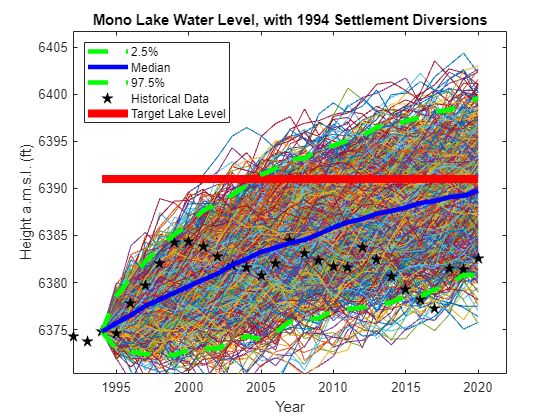

% **Calculate the 0.025, 0.5, 0.975 quantiles for each year and then plot each row.
% Plot 2.5% and 97.5% with thick dashed lines and median with thick solid line.
probs = quantile (Z_model_MC', [0.025, 0.5, 0.975]);
plot(t,Z_model_MC)
hold on
p4 = plot(1983:2020, Z_measured(YR_measured>=1983 & YR_measured<=2020), 'pentagram', 'MarkerSize', 8, 'Color', [0 0 0], 'MarkerFaceColor', [0 0 0]);
p5 = plot(t,targetlevel,"Color",[1 0 0],"LineWidth",6);
p1 = plot (t, probs (3,:), '--', 'Color', 'g', 'LineWidth', 3.5);
p2 = plot (t, probs (1,:), '--', 'Color', 'g', 'LineWidth', 3.5);
p3 = plot (t, probs (2,:), 'Color', 'b', 'LineWidth', 3.5);
% Add labels
legend ([p1 p3 p2 p4 p5], {'2.5%', 'Median', '97.5%','Historical Data', 'Target Lake Level'}, "Location","northwest")
xlabel('Year')
ylabel('Height a.m.s.l. (ft)')
title('Mono Lake Water Level, with 1994 Settlement Diversions')
xlim([1992.0 2022.0])
ylim([6370.3 6406.7])
hold off
% Use saveas(gcf, 'filename.png') to save the current plot as a png file in your working directory.
saveas (gcf, 'MonteCarloModel2020.png')

## 7.  Run some experiments

Your code should now be easily modifiable to explore other time frames. Here are some ideas to get started.

- 1994 to 2020, careful with time period beyond historical data (try using logical indexes)!

- 1994 to 2020 with different diversion rules.

- 2015 to 2020 with current rules and new rules from 2020 onward.

##  8.  Evaluate the results

- Based on your model what was the probability that the 1994 settlement would result in the desired lake level of 6391 feet by 2014?

probs2014 = quantile (Z_model_MC', [0.01:0.01:1.00]); %quantile for each percentage
probs2014 = probs2014(:, end-6); %only 2014
probs2014 = probs2014./(10^3); %remove ten powers for rounding
probs2014 = round(probs2014,3); %round down decimal places for logical indexing
element2014 = probs2014==6.3910; %logical indexer
element2014=find(element2014==1); %identify probabilities of 6391

probability2014atorabove6391upperbound = 28

probability2014atorabove6391upperbound = 100 - element2014(1)

probability2014atorabove6391lowerbound = 23

probability2014atorabove6391lowerbound = 100 - element2014(end)

    Probability varies based upon the model

- Based on your model what was the probability that the lake level would have been at the observed elevation in 2017?

probs2017 = quantile (Z_model_MC', [0.01:0.01:1.00]); %quantile for each percentage
probs2017 = probs2017(:, end-3); %only 2017
probs2017 = probs2017./(10^3); %remove ten powers for rounding
probs2017 = round(probs2017,3); %round down decimal places for logical indexing
element2017 = probs2017==6.3910; %logical indexer
element2017 = find(element2017==1); %identify probabilities of 6391

probability2017atorabove6391upperbound = 36

probability2017atorabove6391upperbound = 100 - element2017(1)

probability2017atorabove6391lowerbound = 31

probability2017atorabove6391lowerbound = 100 - element2017(end)

- California experienced droughts in 1928-34, 1976-77, 1987-92, 2001-02, 2007-09 and 2012-16. How would these droughts effect our model assumptions and results?

Our model assumes quantities in any individual year are based upon historical averages and historical range of variation; however, it assumes a normal distribution of data, which does not necessarily fit California's weather patterns. Extreme events occur in California at a rate greater than only 5% of years being assumed to be outside of two standard deviations, and are uncommonly sustained (the model doesn't predict multiyear droughts) and may be correlated (our model does not account for correlation in extremes). It additionally does not include for the likely increase in the frequency and magnitude of severity of drought in California in the coming years. As such, it is likely our model will overestimate water levels, particularly given the frequency of drought began to increase dramatically in California after 1983.

## 9. Final Report

Draft a recommendation for future LAWPD diversions from the Mono Basin. Your recommendation should use your model results and attempt to balance Los Angeles water needs with Mono Lake recovery.

- Prepare a written report that includes a brief executive summary that describes your policy recommendation and uses results from your model(s) to justify your diversion choices. This summary should be followed by an outline of the modeling process (use the modeling process outline) and appendices with your MATLAB model scripts.

- Prepare a 2-3 slide presentation to present your recommendations to the California Water Board. Come prepared to our next class ready to present and argue for your recommendations in front of the class.